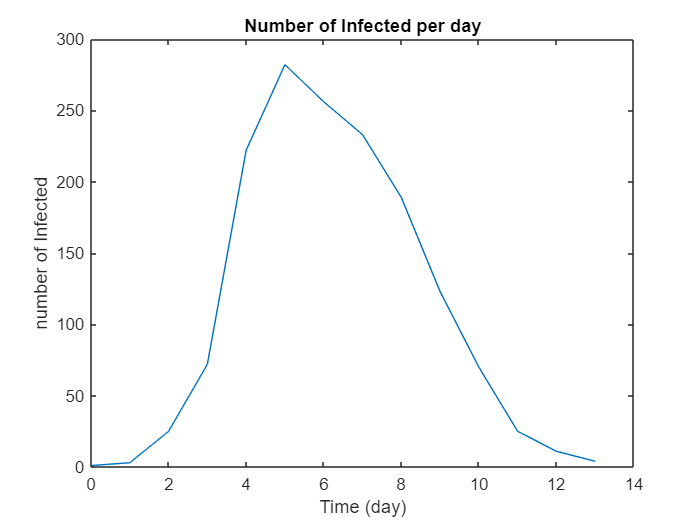

close all

syms xdata ydata
xdata = [0,1,2,3,4,5,6,7,8,9,10,11,12,13];
ydata = [1,3,25,72,222,282,256,233,189,123,70,25,11,4];

pop = 763;

a = 0.003;
b = 0.4;
c = 0.04;
xt0 = [762, 1, 0];

%Assume v% of infected students are bedridden
v = 100;

plot(xdata, min((100/v)*ydata, pop))
xlabel('Time (day)')
ylabel('number of Infected')
title("Number of Infected per day")

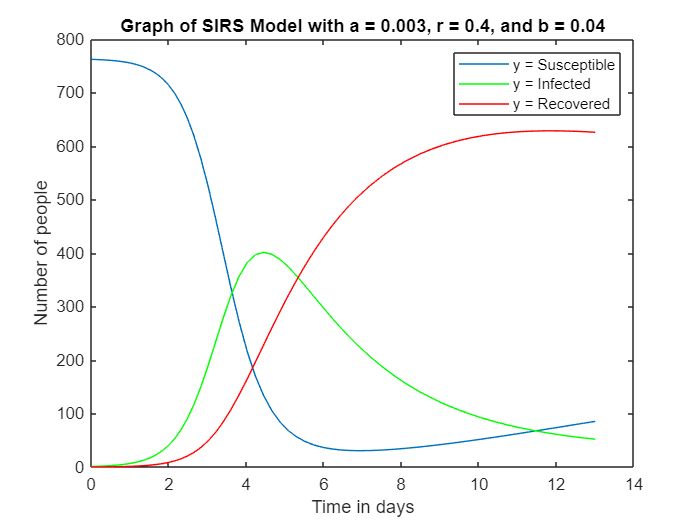

f = @(t,x) [-a*x(1)*x(2) + c*x(3);a*x(1)*x(2)-b*x(2);b*x(2) - c*x(3)];

[t,xa]=ode45(f,[0 13], xt0);
 plot(t,min(xa(:,1), pop))
 hold on
 plot(t,min(xa(:,2), pop),'g')
 plot(t,min(xa(:,3), pop),'r')

 title('Graph of SIRS Model with a = 0.003, r = 0.4, and b = 0.04')
 xlabel('Time in days')
 ylabel('Number of people')
 legend({'y = Susceptible','y = Infected', 'y = Recovered'},'Location','northeast')
 hold off

a = 0.003;
b = 0.4;
c = 0.04;
xt0 = [762, 1, 0];

xdata = [0,1,2,3,4,5,6,7,8,9,10,11,12,13];
ydata = [1,3,25,72,222,282,256,233,189,123,70,25,11,4];

y(1) = a;
y(2) = b;

[abest, xbest] = lsqcurvefit(@sirsfunction2, [a,b,c] ,xdata, min((100/v)*ydata, pop), [0,0,0]);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



fprintf('New parameters: %f, %f, %f',[abest(1), abest(2), abest(3)])

New parameters: 0.002566, 0.482896, 0.000000

fprintf('Original parameters: %f, %f, %f',[a,b,c])

Original parameters: 0.003000, 0.400000, 0.040000


a = abest(1)

a = 0.0026

b = abest(2)

b = 0.4829

c = abest(3) 

c = 3.9335e-09

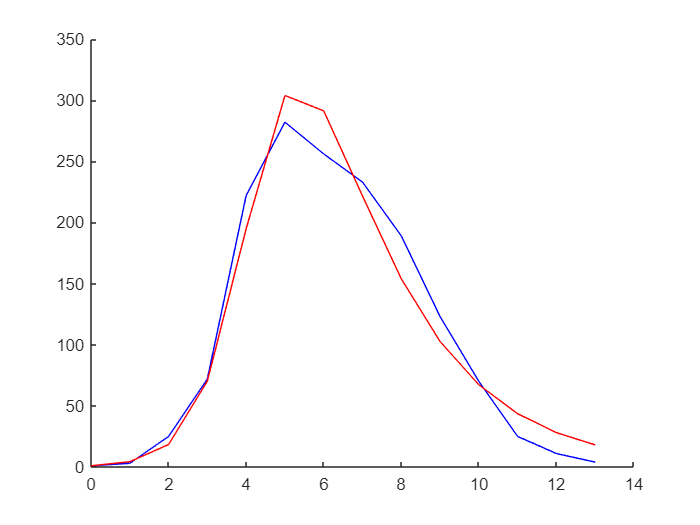


figure
hold on
plot(xdata, min((100/v)*ydata, pop), 'b')
plot(xdata, min(sirfunction2([a,b,c], xdata), pop), 'r')

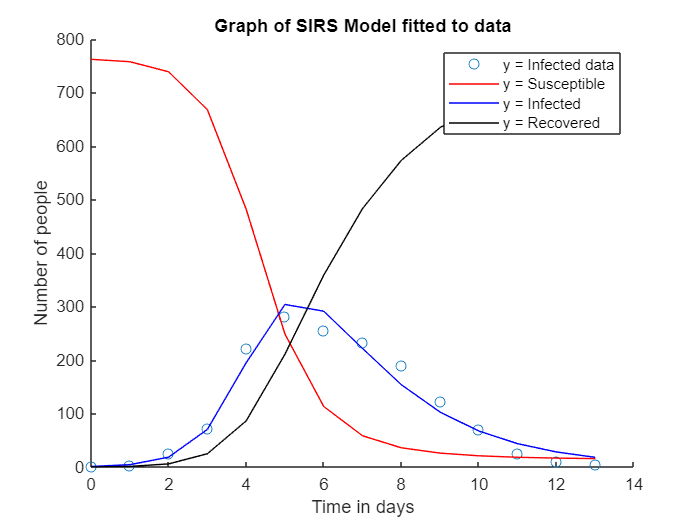

figure
hold on
plot(xdata, min((100/v)*ydata, pop), 'o')
plot(xdata, min(sirsfunction([a,b,c], xdata), pop), 'r')
plot(xdata, min(sirsfunction2([a,b,c], xdata), pop), 'b')
plot(xdata, min(sirsfunction3([a,b,c], xdata), pop), 'k')

title('Graph of SIRS Model fitted to data')
 xlabel('Time in days')
 ylabel('Number of people')
 legend({'y = Infected data','y = Susceptible','y = Infected', 'y = Recovered'},'Location','northeast')


(sirsfunction([a,b,c], xdata) + sirsfunction2([a,b,c], xdata) + sirsfunction3([a,b,c], xdata))/pop

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


R0 = (a+c)/b

R0 = 0.0053


RSS = sum((min((100/v)*ydata, pop) - min(sirsfunction2([a,b,c], xdata), pop)).^2);
TSS = sum((min((100/v)*ydata, pop) - min((100/v)*mean(ydata), pop)).^2);
R_sq = 1 - (RSS/TSS)

R_sq = 0.9651